# Introduction

Implementation of Spiliopoulos' inter-bank reserves model with common noise


$$\mathrm{d}X_t^i = a_{i}\left(\bar{X}_t-X_t^i\right) \mathrm{d}t + \sigma_{i}\mathrm{~d}\widetilde{W}^{i}_{t} $$


where $\mathrm{~d}\widetilde{W}^{i}_{t} := \rho \mathrm{d}W_t^0 + \sqrt{1-\rho^2} \mathrm{~d}W_t^i$, with $W^{i}$ the individual noises and $W^{0}$ the common noise and $|\rho| \leq 1$

# Baseline

Homogeneous banks ($a = 1, \sigma = 1$), no common noise


$$\mathrm{d}X_t^i = \left(\bar{X}_t-X_t^i\right) \mathrm{d}t + \mathrm{~d}W^{i}_{t}$$


baseline = model(10, ones(10, 1), ones(10, 1));
baseline = baseline.sde_euler;
baseline = baseline.monte_carlo(5000);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 6).


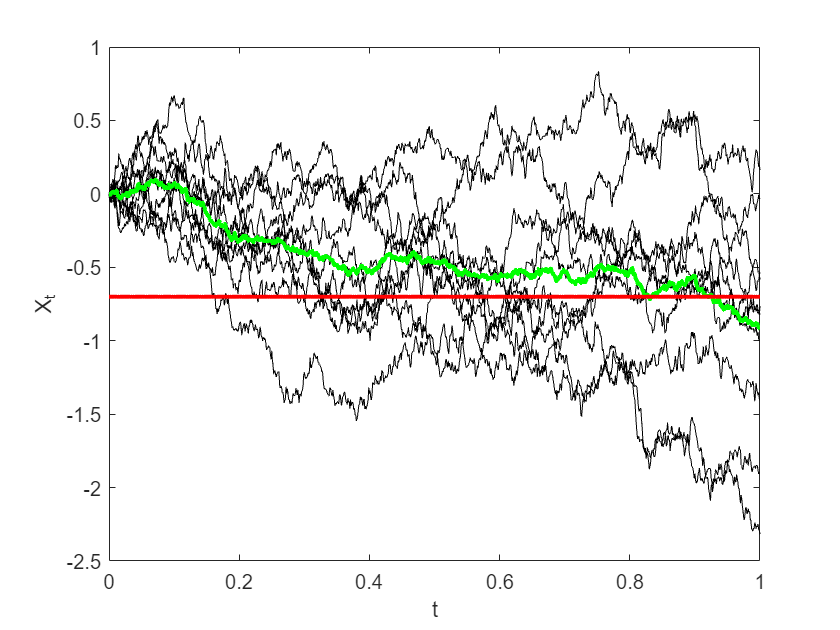

plot_trajectory(baseline);

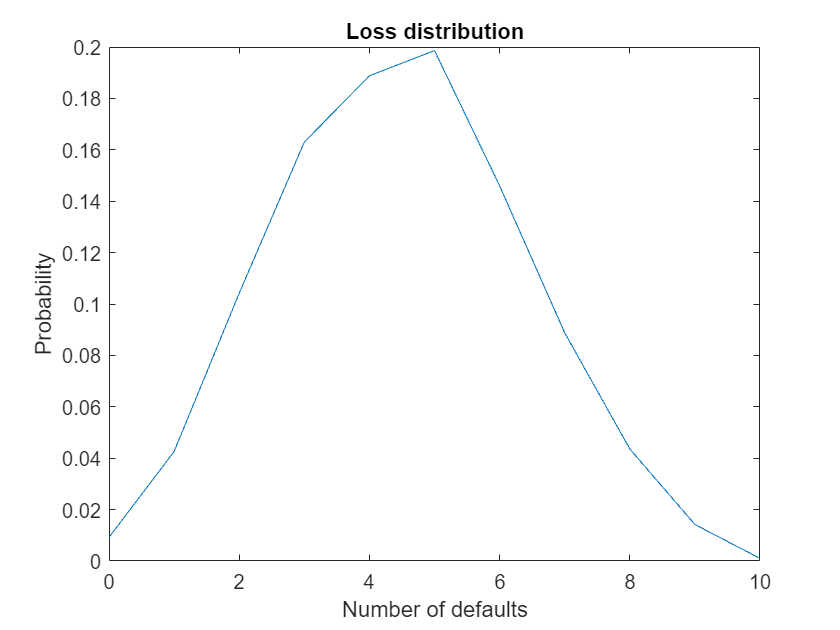

baseline.plot_loss;

fprintf("Probability of systemic failure: %.2f", baseline.probfail);

# Homogeneous, common-noise


$$\mathrm{d}X_t^i = \left(\bar{X}_t-X_t^i\right) \mathrm{d}t + \mathrm{~d}\widetilde{W}^{i}_{t}$$


Varying $\rho$: 0.2, 0.4, 0.6, 0.8

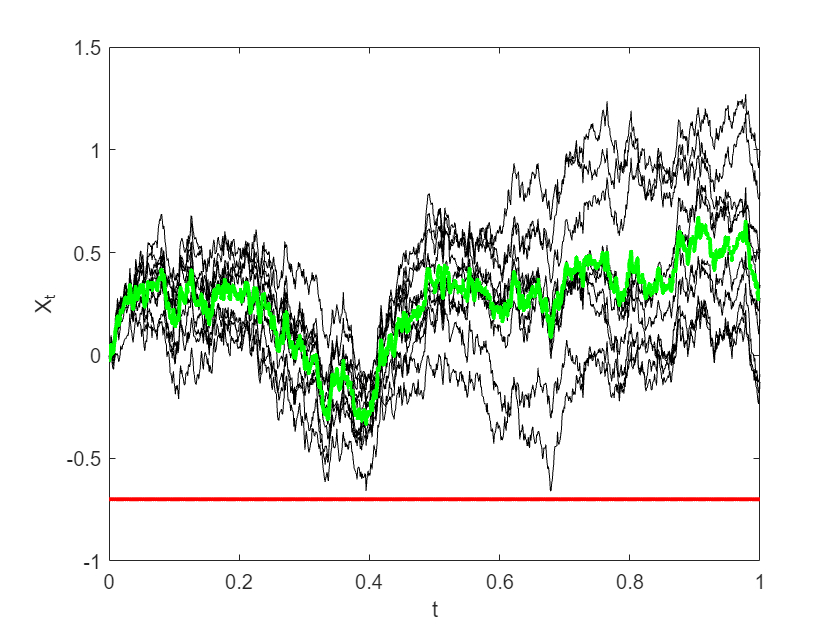

baseline_cn = baseline.common_noise(0.9);
baseline_cn = baseline_cn.sde_euler;
baseline_cn = baseline_cn.monte_carlo(5000);
baseline_cn.plot_trajectory;

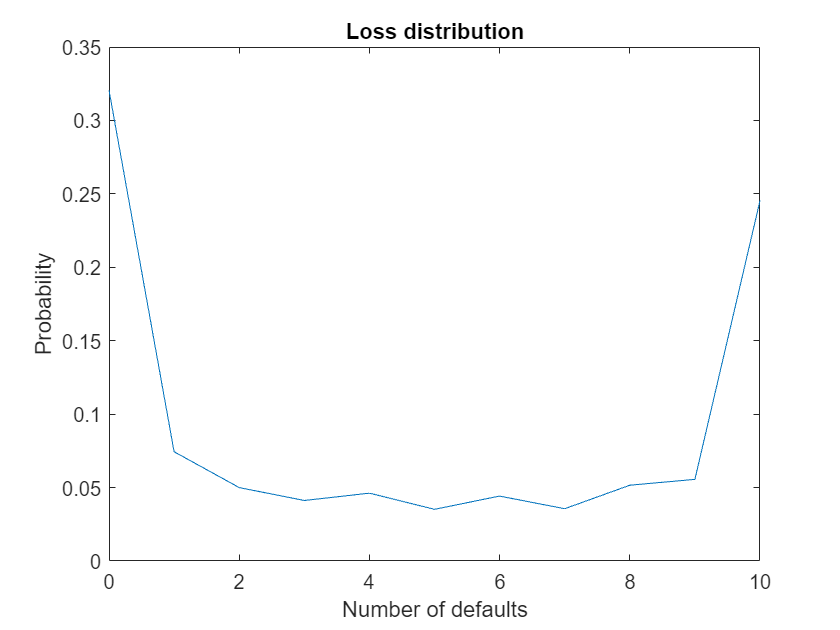

baseline_cn.plot_loss;

fprintf("Probability of systemic failure: %.2f", baseline_cn.probfail);

Probability of systemic failure: 0.41

baseline_cn_1 = baseline.common_noise(0.2);
baseline_cn_1 = baseline_cn_1.sde_euler;
baseline_cn_1 = baseline_cn_1.monte_carlo(5000);

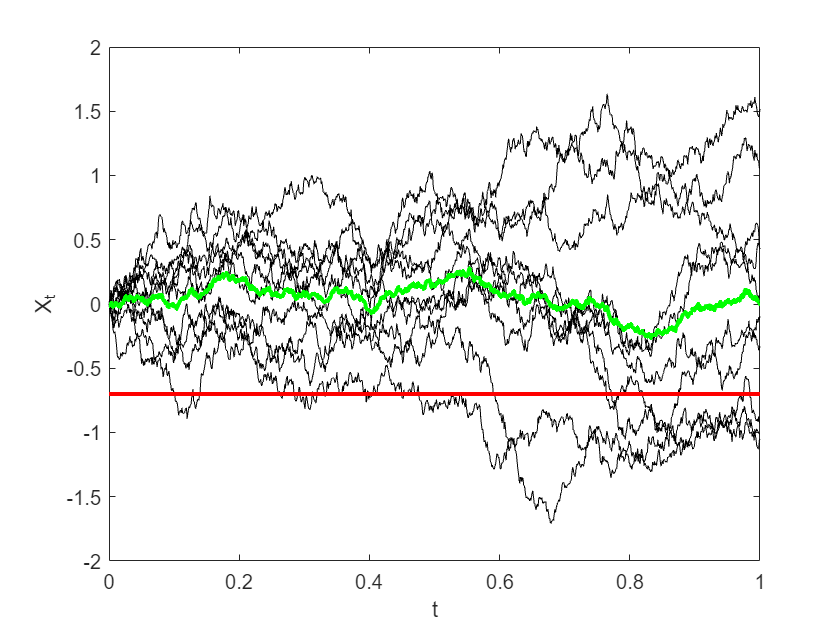

baseline_cn_1.plot_trajectory;

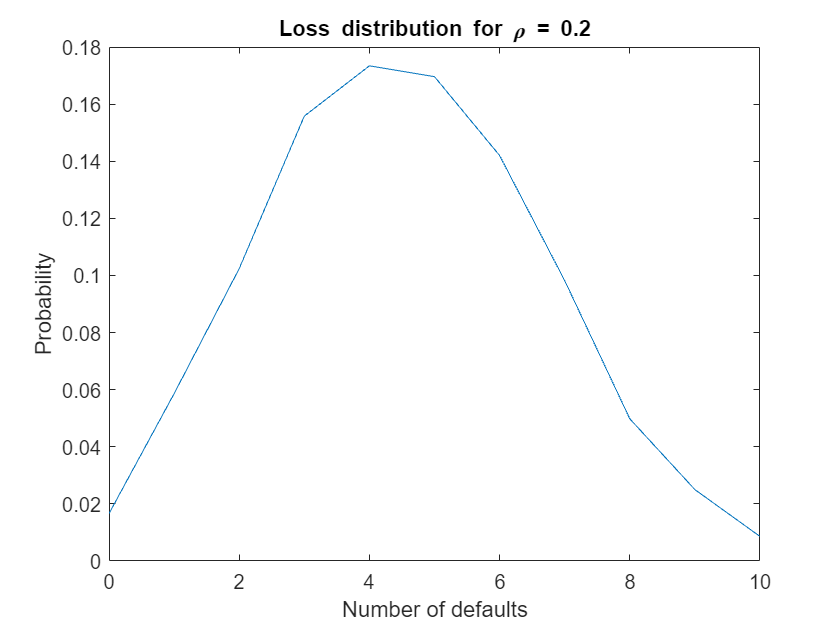

baseline_cn_1.plot_loss;
title("Loss distribution for \rho = 0.2");

fprintf("Probability of systemic failure: %.2f", baseline_cn_1.probfail);

Probability of systemic failure: 0.05

baseline_cn_2 = baseline.common_noise(0.4);
baseline_cn_2 = baseline_cn_2.sde_euler;
baseline_cn_2 = baseline_cn_2.monte_carlo(5000);

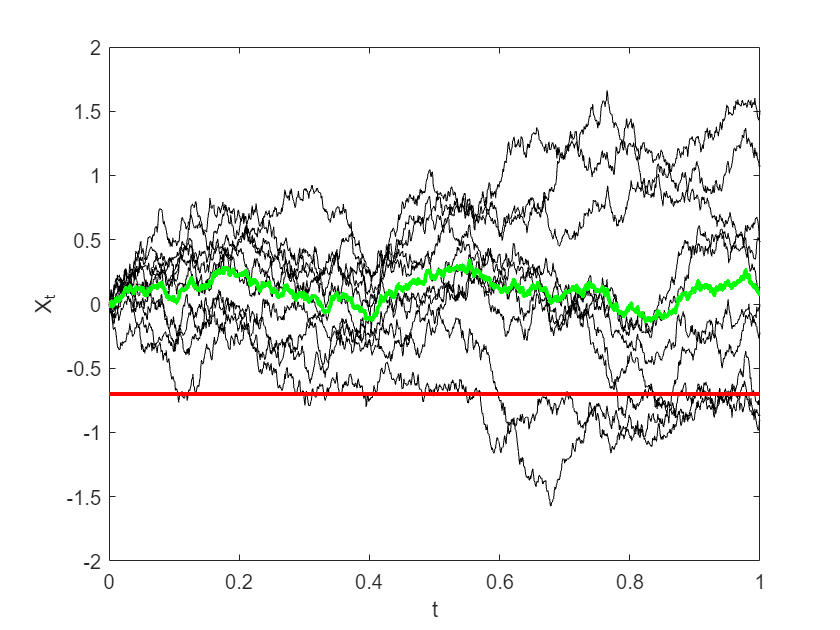

baseline_cn_2.plot_trajectory;

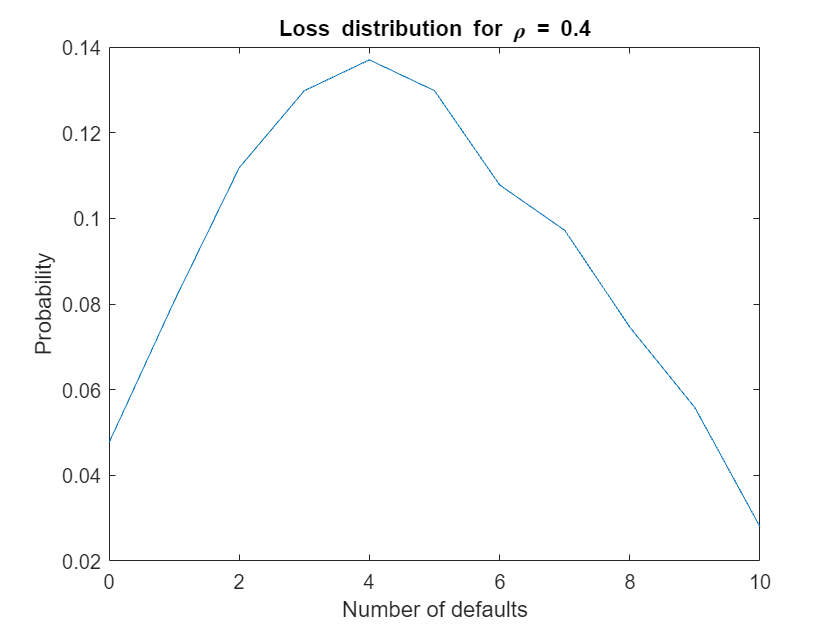

baseline_cn_2.plot_loss;
title("Loss distribution for \rho = 0.4");

fprintf("Probability of systemic failure: %.2f", baseline_cn_2.probfail);

Probability of systemic failure: 0.16

baseline_cn_3 = baseline.common_noise(0.6);
baseline_cn_3 = baseline_cn_3.sde_euler;
baseline_cn_3 = baseline_cn_3.monte_carlo(5000);

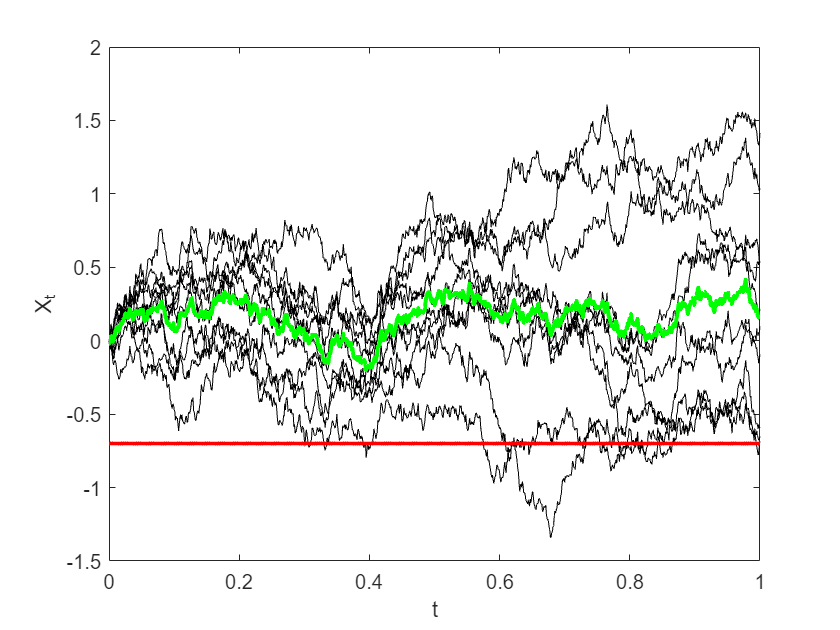

baseline_cn_3.plot_trajectory;

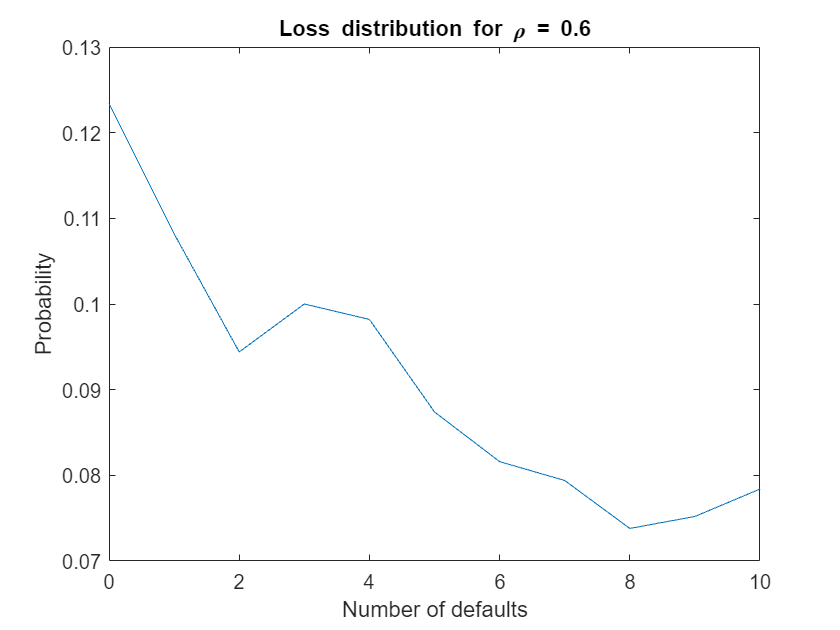

baseline_cn_3.plot_loss;
title("Loss distribution for \rho = 0.6");

fprintf("Probability of systemic failure: %.3f", baseline_cn_3.probfail);

Probability of systemic failure: 0.268

baseline_cn_4 = baseline.common_noise(0.8);
baseline_cn_4 = baseline_cn_4.sde_euler;
baseline_cn_4 = baseline_cn_4.monte_carlo(5000);

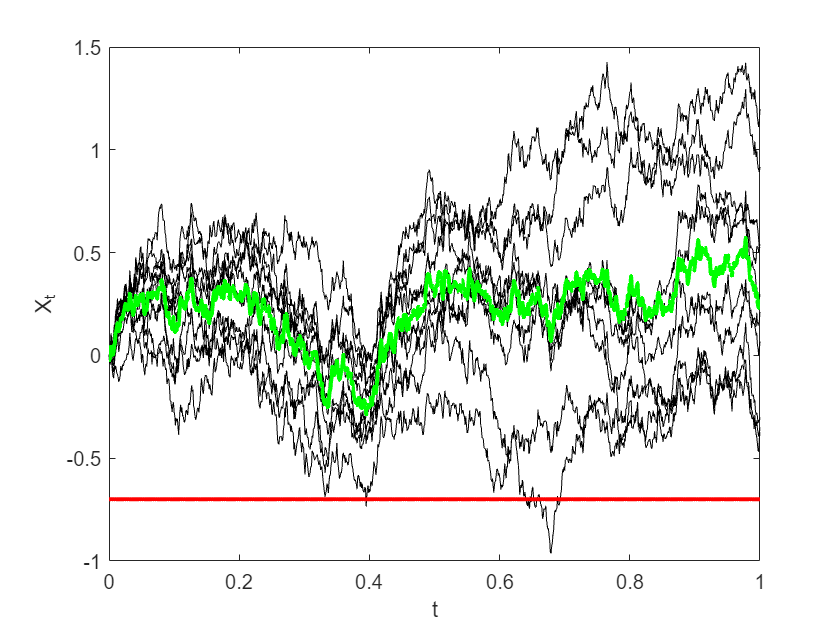

baseline_cn_4.plot_trajectory;

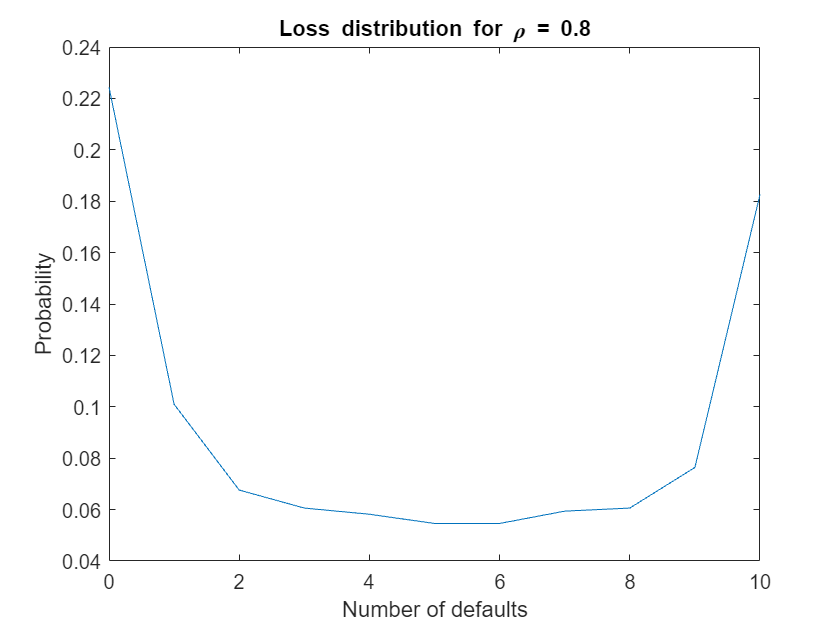

baseline_cn_4.plot_loss;
title("Loss distribution for \rho = 0.8");

fprintf("Probability of systemic failure: %.2f", baseline_cn_4.probfail);

Probability of systemic failure: 0.39

# Group A


$$\mathrm{d}X_t^i = a_{i}\left(\bar{X}_t-X_t^i\right) \mathrm{d}t + \sigma_{i}\mathrm{~d}W^{i}_{t} $$



$$\left\{(a, \sigma)_{\left\{1, 2\right\}}, (a, \sigma)_{\left\{3, 4, 5, 6, 7\right\}}, (a, \sigma)_{\left\{8, 9, 10\right\}} \right\} = \left\{(1, 2), (10, 1), (100, 0.5)\right\}$$


Agents with small coefficients $a_i$ have large coefficients $\sigma_i$,while agents with large coefficients $a_i$ have small coefficients $\sigma_i$.

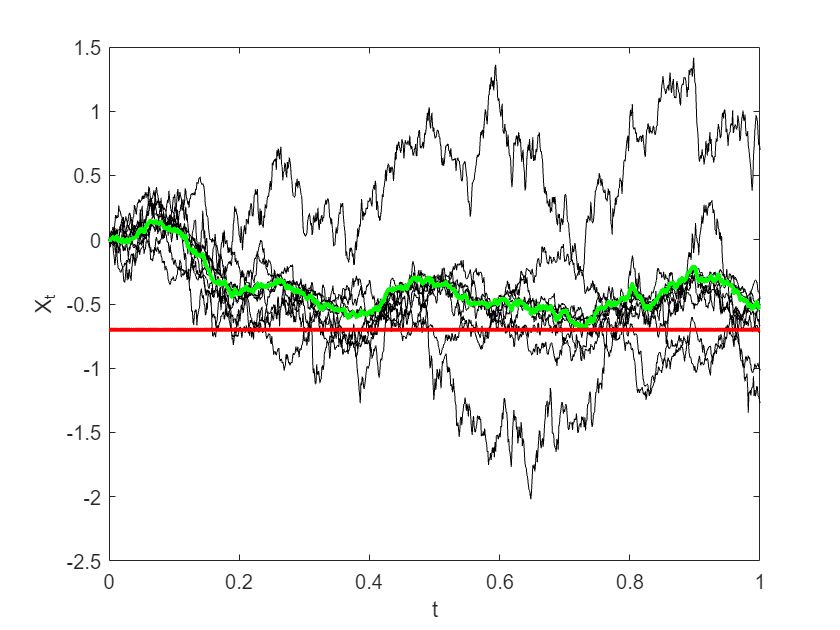

model_A = model(10, ...
    [repelem(1, 2, 1); repelem(10, 5, 1); repelem(100, 3, 1)], ...
    [repelem(2, 2, 1); repelem(1, 5, 1); repelem(0.5, 3, 1)] ...
    );
model_A = model_A.sde_euler;
model_A.plot_trajectory;

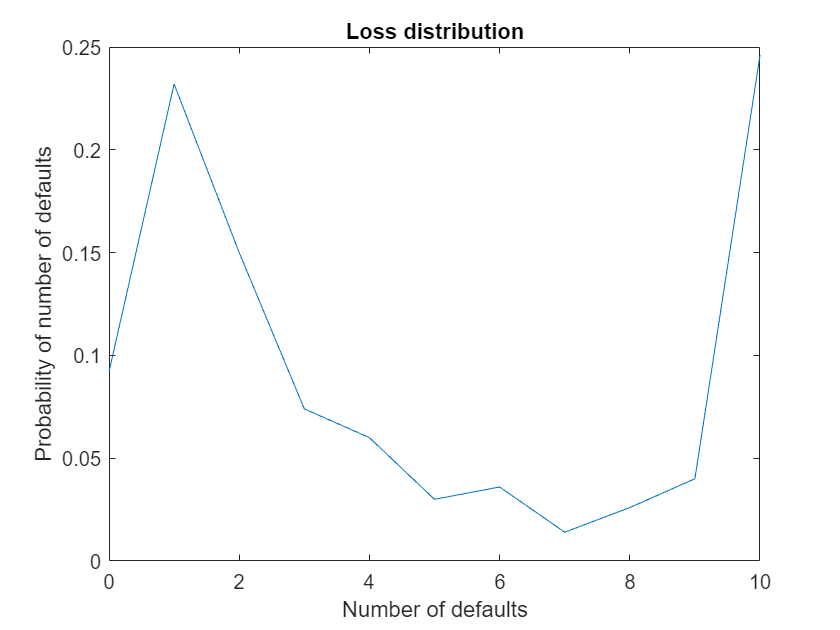

model_A.plot_loss;

## Common noise

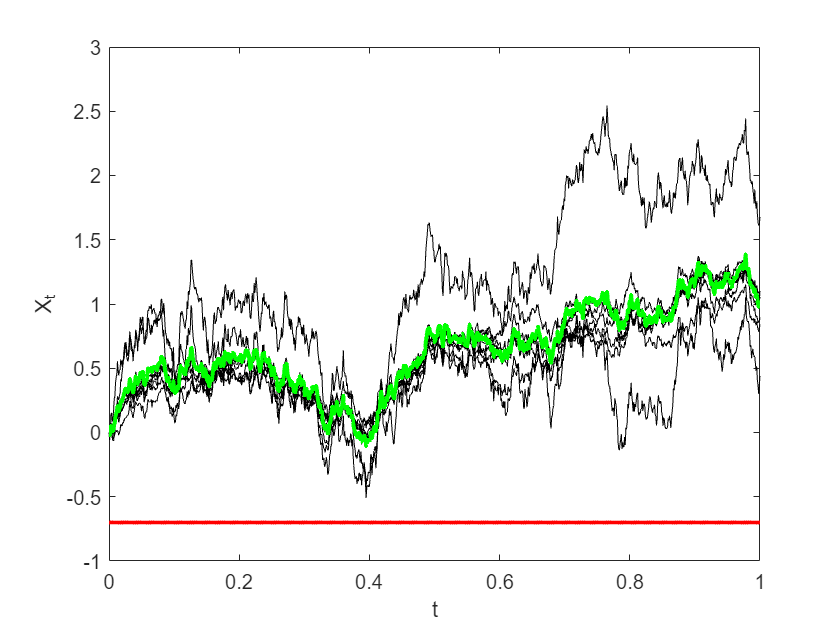

model_A_cn = model_A.common_noise(0.9);
model_A_cn = model_A_cn.sde_euler;
model_A_cn.plot_trajectory;

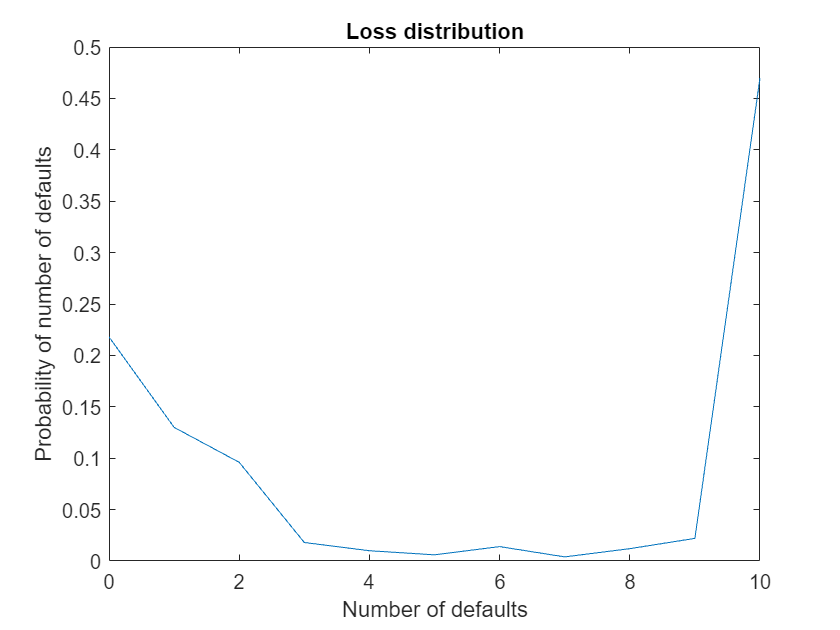

model_A_cn.plot_loss;

# Group B


$$\mathrm{d}X_t^i = a_{i}\left(\bar{X}_t-X_t^i\right) \mathrm{d}t + \sigma_{i}\mathrm{~d}W^{i}_{t} $$



$$\left\{(a, \sigma)_{\left\{1, 2\right\}}, (a, \sigma)_{\left\{3, 4, 5, 6, 7\right\}}, (a, \sigma)_{\left\{8, 9, 10\right\}} \right\} = \left\{(1, 0.5), (10, 1), (100, 2)\right\}$$


Agents with small coefficients $a_i$ have also small coefficients $\sigma_i$ and agents with large coefficients $a_i$ also have large coefficients $\sigma_i$.

model_B = model(10, ...
    [repelem(1, 2, 1); repelem(10, 5, 1); repelem(100, 3, 1)], ...
    [repelem(2, 2, 1); repelem(1, 5, 1); repelem(0.5, 3, 1)] ...
    );
model_B = model_B.sde_euler;
model_B.plot_trajectory;

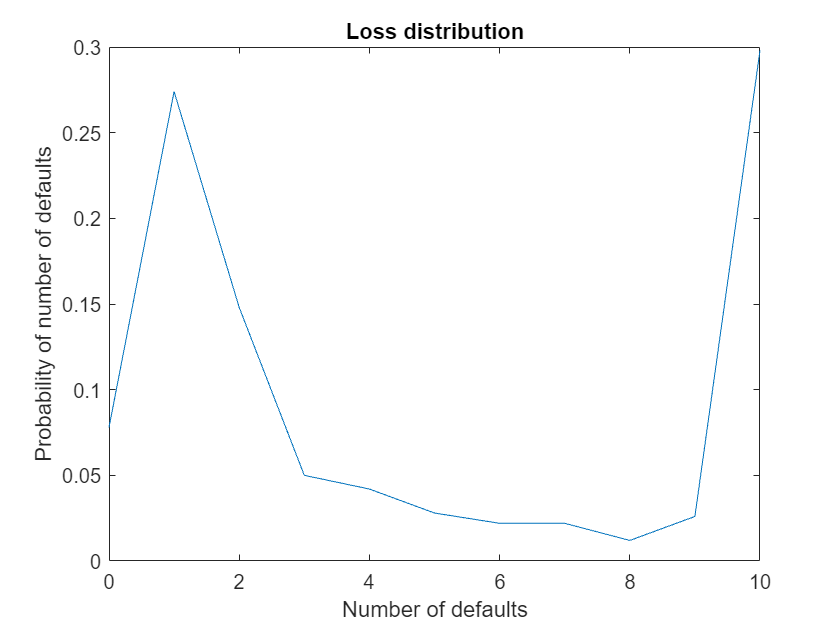

model_B.plot_loss;

## Common noise

model_B_cn = model_B.common_noise(0.9);
model_B_cn = model_B_cn.sde_euler;
model_B_cn.plot_trajectory;

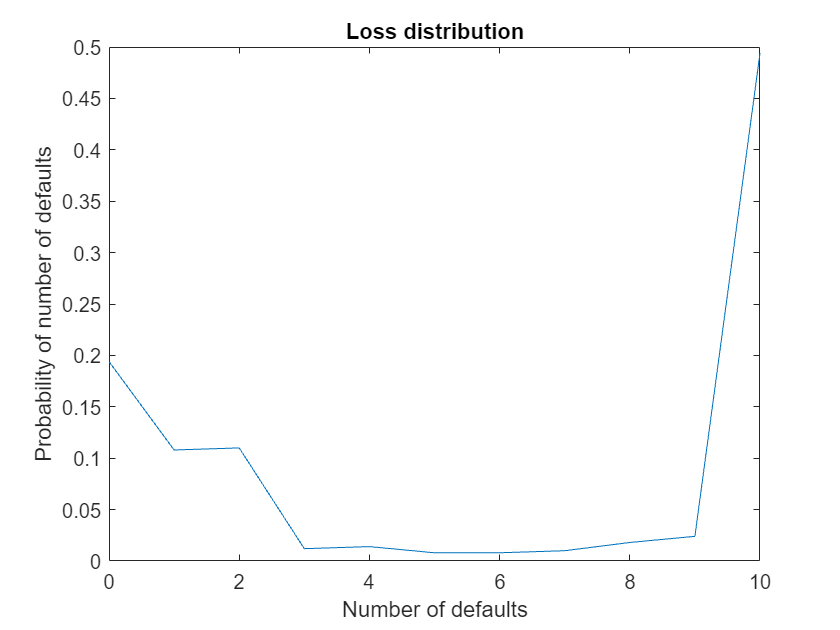

model_B_cn.plot_loss;

# Group A

## Case 1: 8:1:1


$$\left\{(a, \sigma)_{\left\{1, \dots, 8 \right\}}, (a, \sigma)_{\left\{9\right\}}, (a, \sigma)_{\left\{10\right\}} \right\} = \left\{(1, 2), (10, 1), (100, 0.5)\right\}$$


Majority small banks

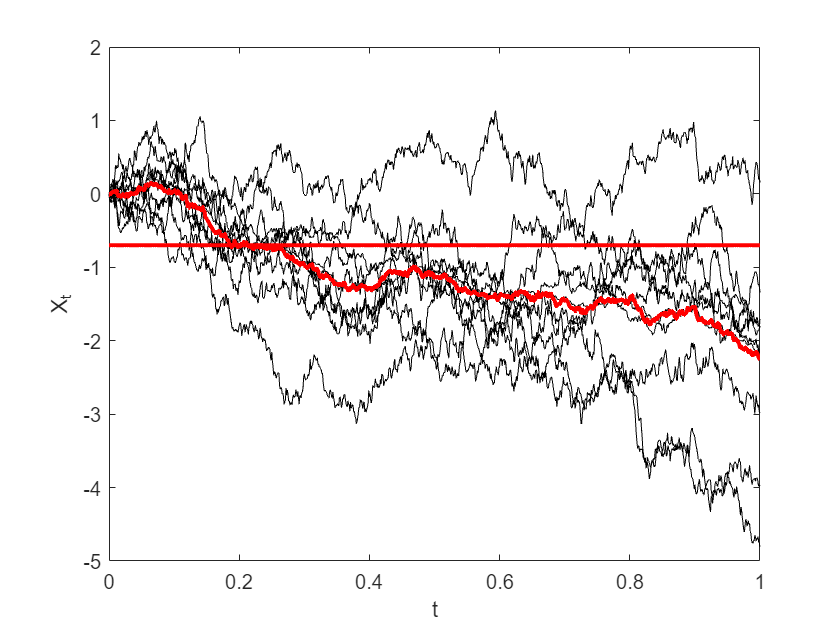

model_A1 = model(10, ...
    [repelem(1, 8, 1); repelem(10, 1, 1); repelem(100, 1, 1)], ...
    [repelem(2, 8, 1); repelem(1, 1, 1); repelem(0.5, 1, 1)] ...
    );
model_A1 = model_A1.sde_euler;
model_A1.plot_trajectory;

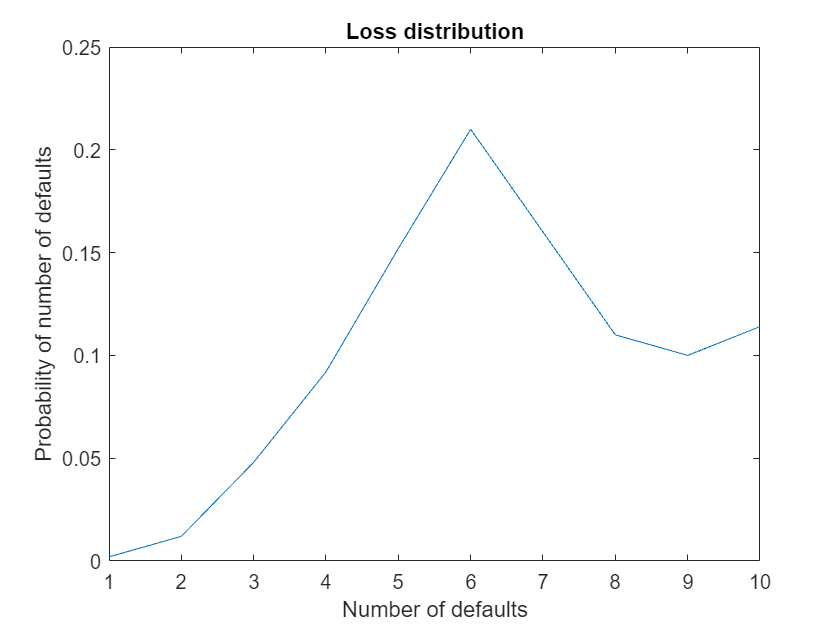

model_A1.plot_loss;

### Common noise

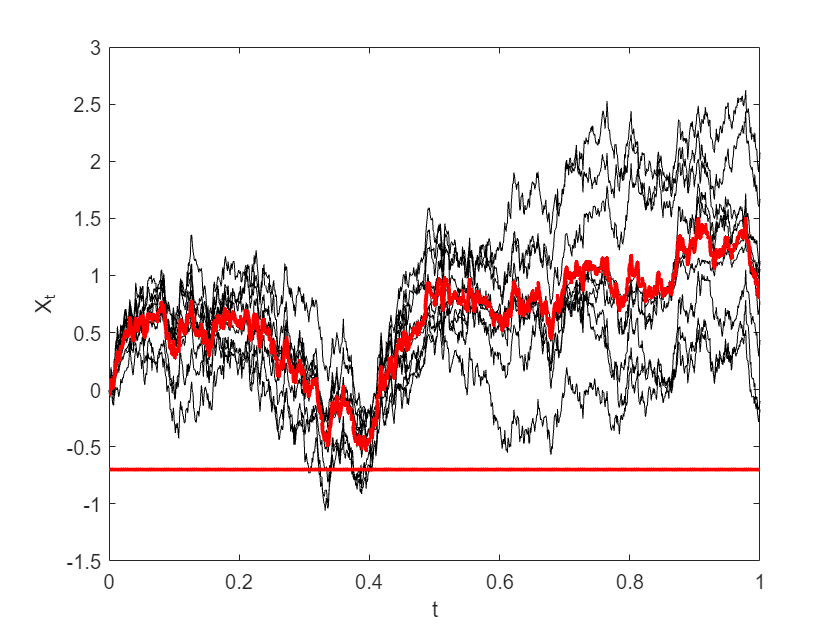

model_A1_cn = model_A1.common_noise(0.9);
model_A1_cn = model_A1_cn.sde_euler;
model_A1_cn.plot_trajectory;

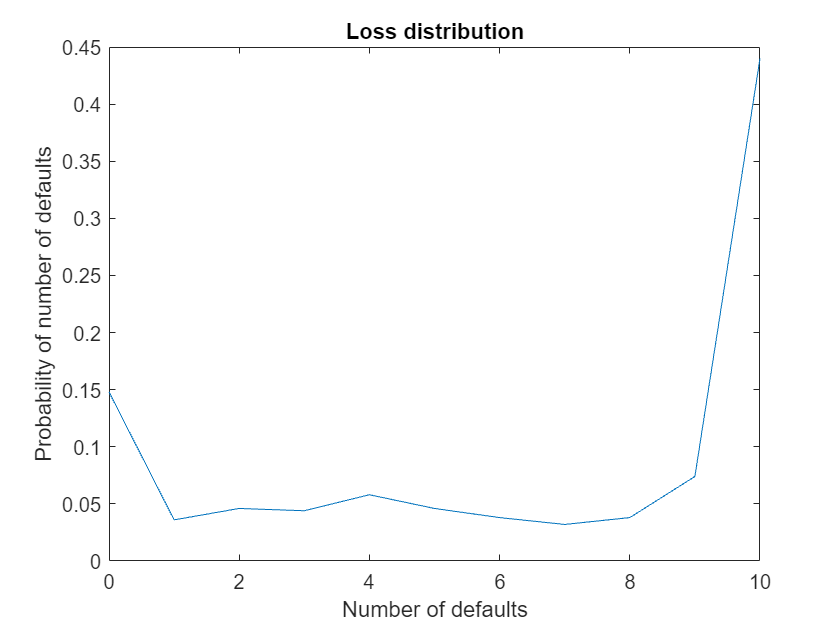

model_A1_cn.plot_loss;

## Case 2: 1:8:1


$$\left\{(a, \sigma)_{\left\{1\right\}}, (a, \sigma)_{\left\{2, \dots, 9\right\}}, (a, \sigma)_{\left\{10\right\}} \right\} = \left\{(1, 2), (10, 1), (100, 0.5)\right\}$$


Majority intermediate banks

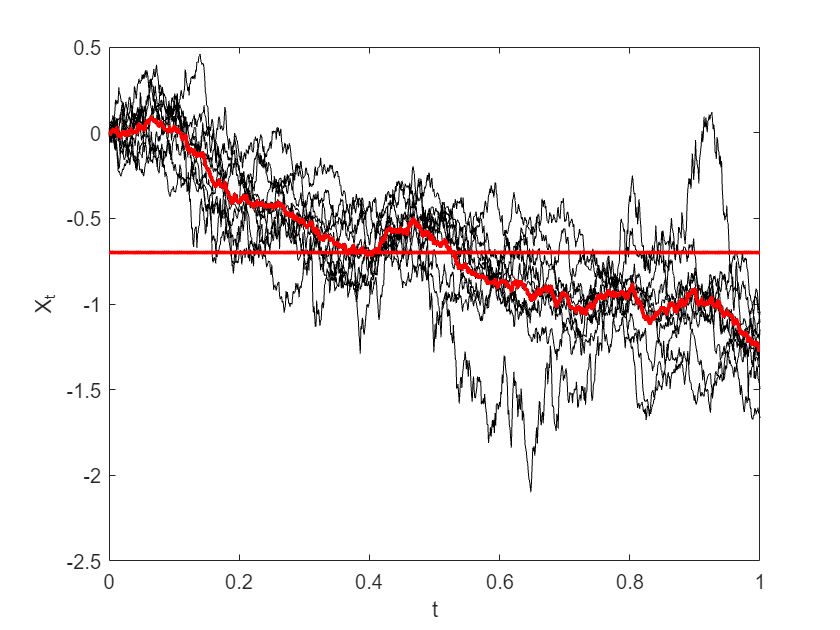

model_A2 = model(10, ...
    [repelem(1, 1, 1); repelem(10, 8, 1); repelem(100, 1, 1)], ...
    [repelem(2, 1, 1); repelem(1, 8, 1); repelem(0.5, 1, 1)] ...
    );
model_A2 = model_A2.sde_euler;
model_A2.plot_trajectory;

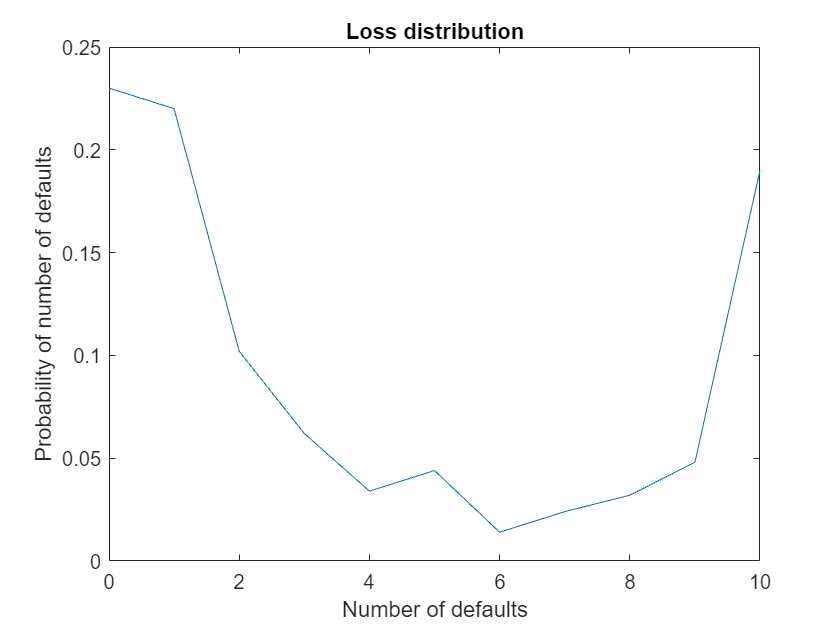

model_A2.plot_loss;

### Common noise

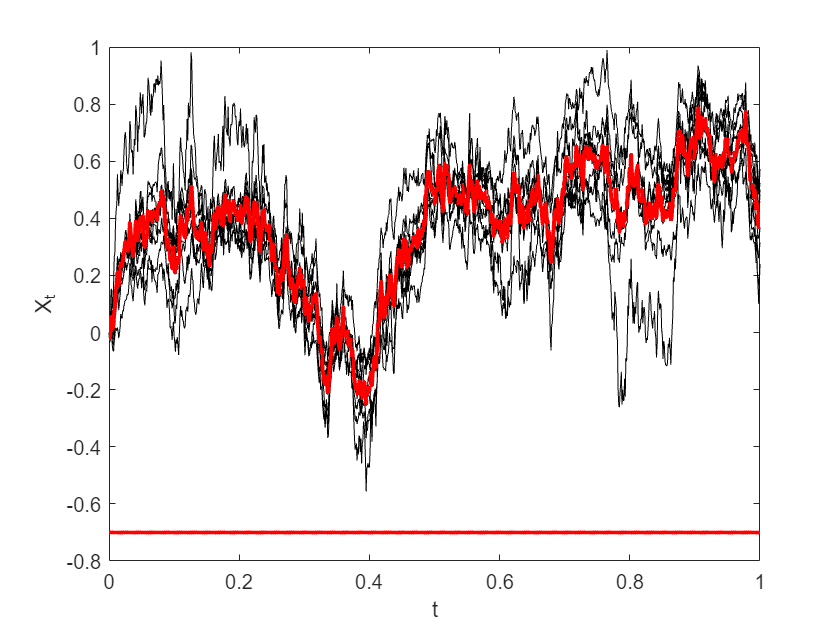

model_A2_cn = model_A2.common_noise(0.9);
model_A2_cn = model_A2_cn.sde_euler;
model_A2_cn.plot_trajectory;

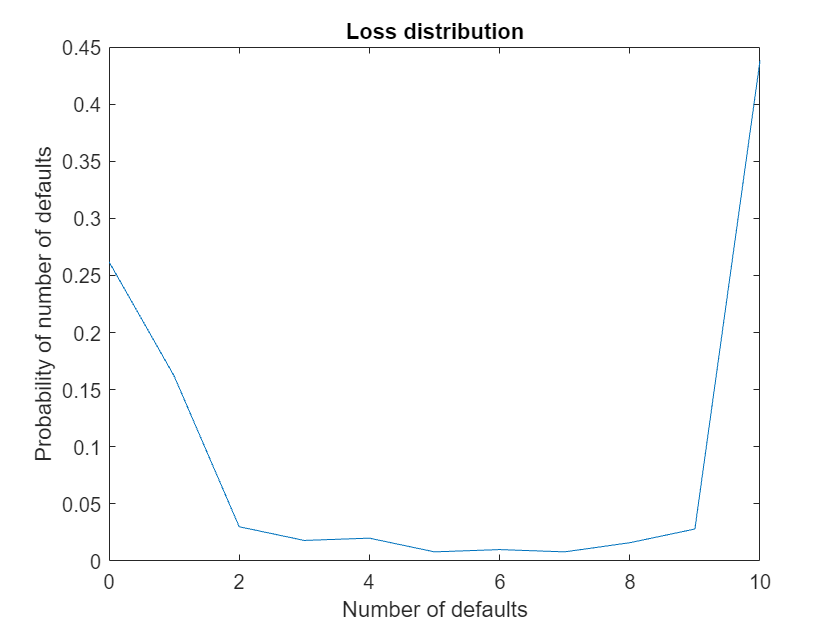

model_A2_cn.plot_loss;

## Case 3: 1:1:8


$$\left\{(a, \sigma)_{\left\{1 \right\}}, (a, \sigma)_{\left\{2\right\}}, (a, \sigma)_{\left\{3, \dots, 10\right\}} \right\} = \left\{(1, 2), (10, 1), (100, 0.5)\right\}$$


Majority large banks

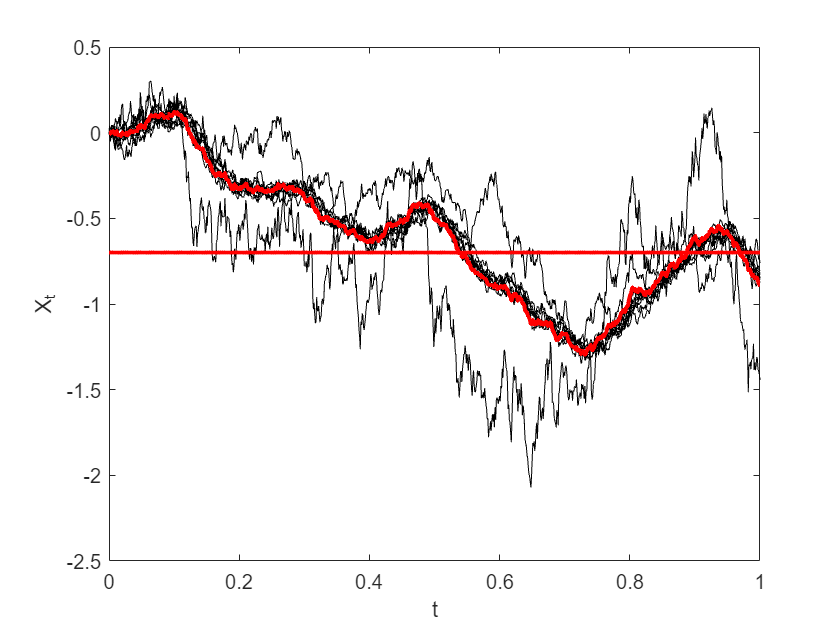

model_A3 = model( ...
    [repelem(1, 1, 1); repelem(10, 1, 1); repelem(100, 8, 1)], ...
    [repelem(2, 1, 1); repelem(1, 1, 1); repelem(0.5, 8, 1)] ...
    );
model_A3 = model_A3.sde_euler;
model_A3.plot_trajectory;

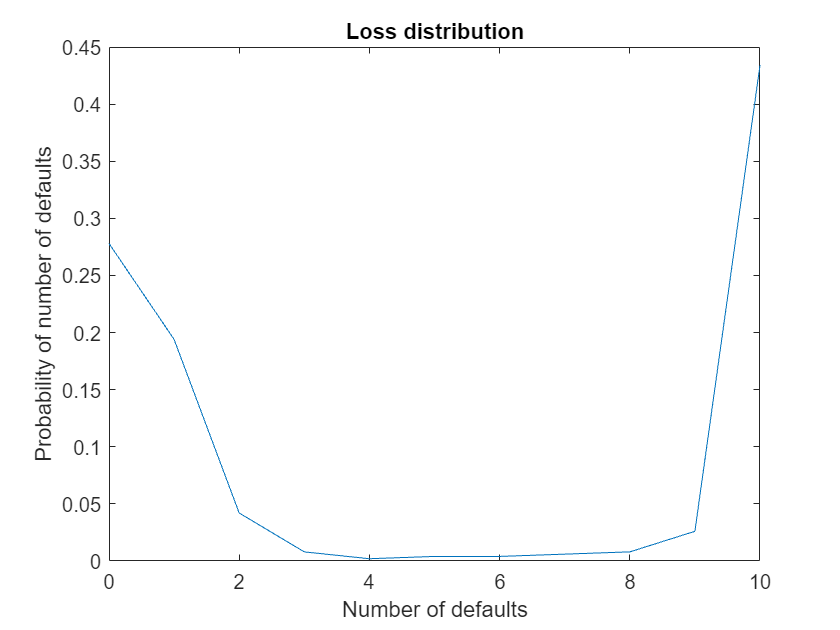

model_A3.plot_loss;

### Common noise

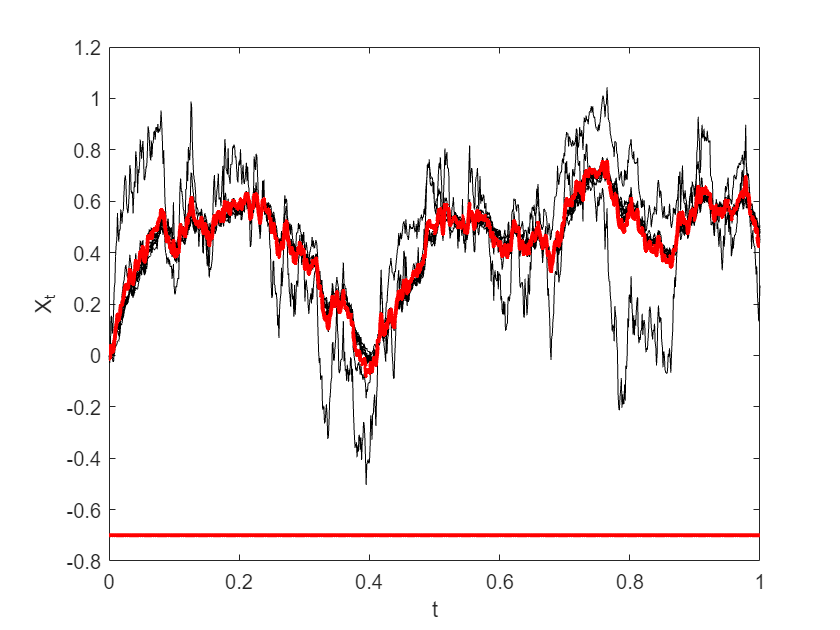

model_A3_cn = model_A3.common_noise(0.9);
model_A3_cn = model_A3_cn.sde_euler;
model_A3_cn.plot_trajectory;

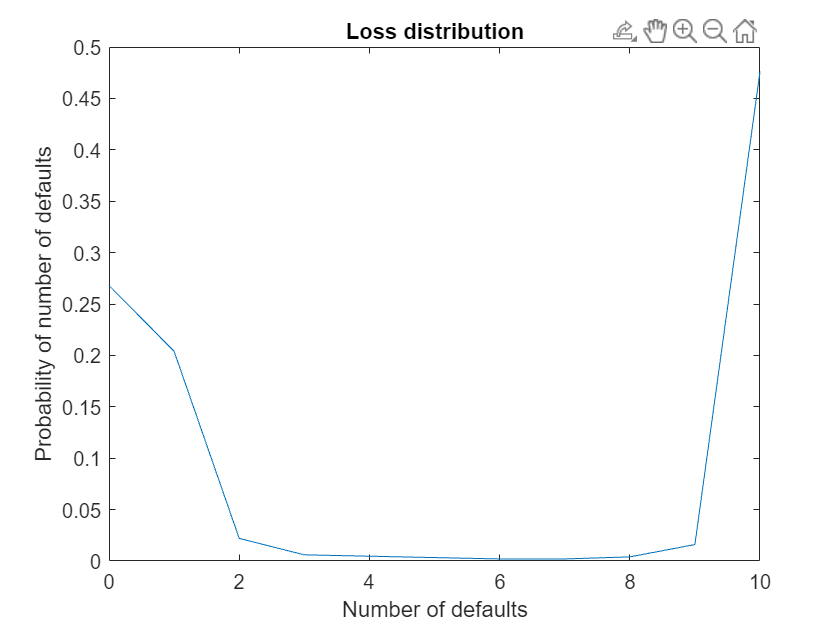

model_A3_cn.plot_loss;

# Group B

## Case 1: 8:1:1


$$\left\{(a, \sigma)_{\left\{1, \dots, 8 \right\}}, (a, \sigma)_{\left\{9\right\}}, (a, \sigma)_{\left\{10\right\}} \right\} = \left\{(1, 0.5), (10, 1), (100, 2)\right\}$$


Majority small banks

model_B1 = model(10, ...
    [repelem(1, 8, 1); repelem(10, 1, 1); repelem(100, 1, 1)], ...
    [repelem(2, 8, 1); repelem(1, 1, 1); repelem(0.5, 1, 1)] ...
    );
model_B1 = model_B1.sde_euler;
model_B1.plot_trajectory;

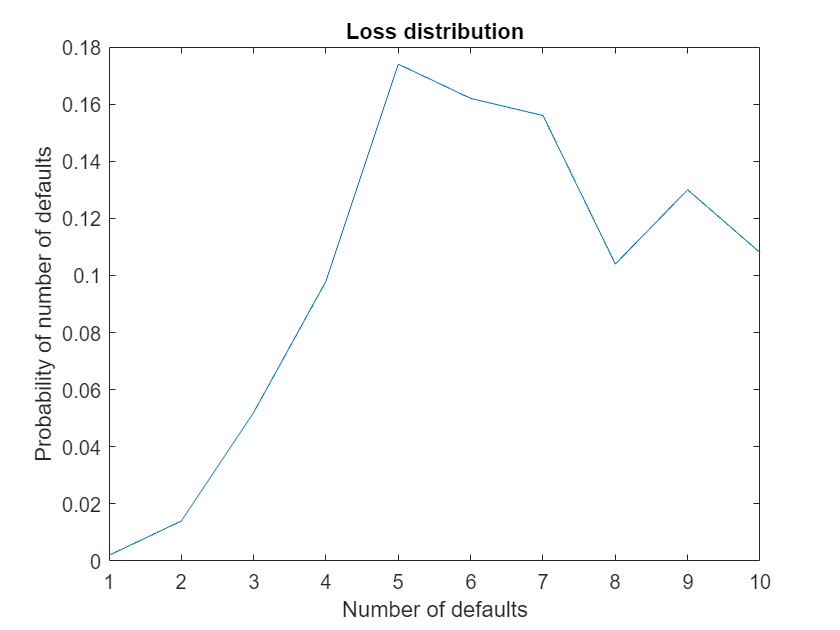

model_B1.plot_loss;

### Common noise

model_B1_cn = model_B1.common_noise(0.9);
model_B1_cn = model_B1_cn.sde_euler;
model_B1_cn.plot_trajectory;

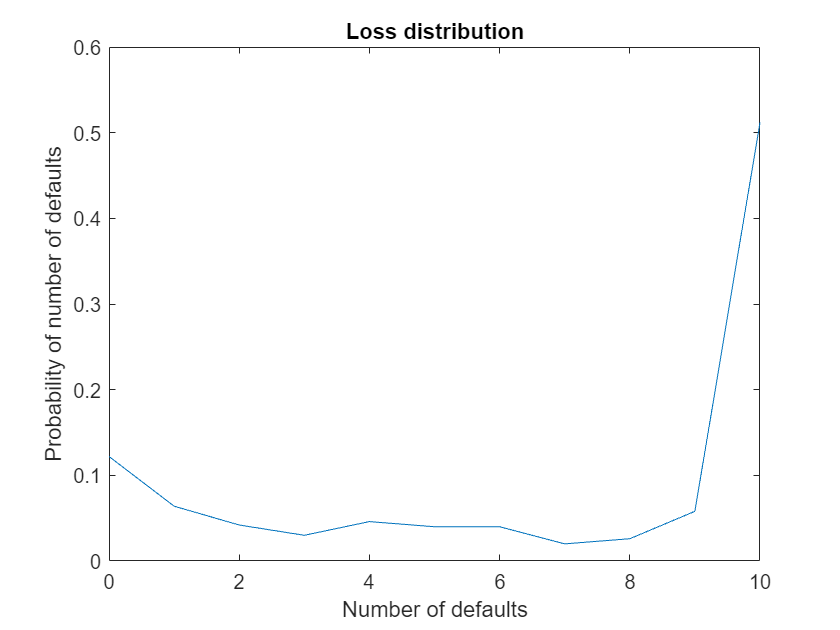

model_B1_cn.plot_loss;

## Case 2: 1:8:1


$$\left\{(a, \sigma)_{\left\{1\right\}}, (a, \sigma)_{\left\{2, \dots, 9\right\}}, (a, \sigma)_{\left\{10\right\}} \right\} = \left\{(1, 0.5), (10, 1), (100, 2)\right\}$$


Majority intermediate banks

model_B2 = model(10, ...
    [repelem(1, 1, 1); repelem(10, 8, 1); repelem(100, 1, 1)], ...
    [repelem(2, 1, 1); repelem(1, 8, 1); repelem(0.5, 1, 1)] ...
    );
model_B2 = model_B2.sde_euler;
model_B2.plot_trajectory;

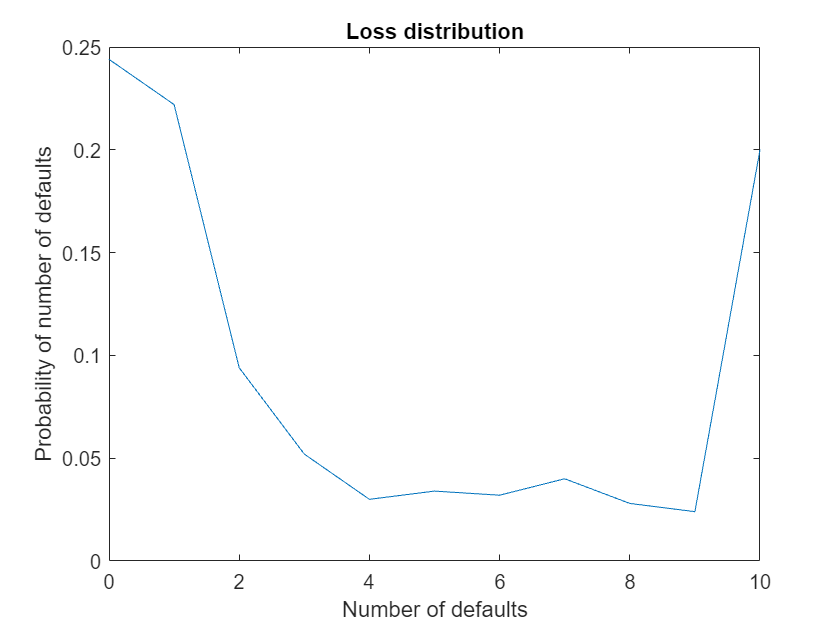

model_B2.plot_loss;

### Common noise

model_B2_cn = model_B2.common_noise(0.9);
model_B2_cn = model_B2_cn.sde_euler;
model_B2_cn.plot_trajectory;

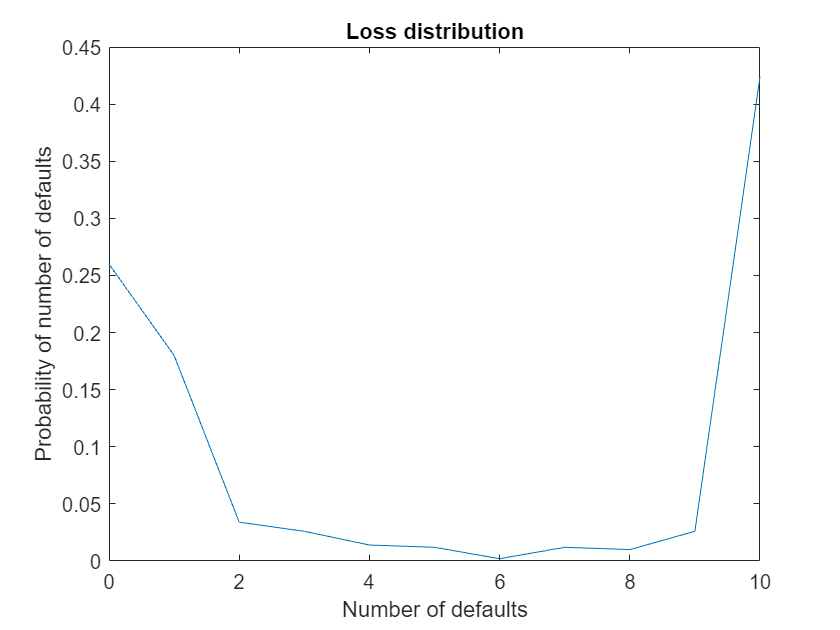

model_B2_cn.plot_loss;

## Case 3: 1:1:8


$$\left\{(a, \sigma)_{\left\{1 \right\}}, (a, \sigma)_{\left\{2\right\}}, (a, \sigma)_{\left\{3, \dots, 10\right\}} \right\} = \left\{(1, 0.5), (10, 1), (100, 2)\right\}$$


Majority large banks

model_B3 = model(10, ...
    [repelem(1, 1, 1); repelem(10, 1, 1); repelem(100, 8, 1)], ...
    [repelem(2, 1, 1); repelem(1, 1, 1); repelem(0.5, 8, 1)] ...
    );
model_B3 = model_B3.sde_euler;
model_B3.plot_trajectory;

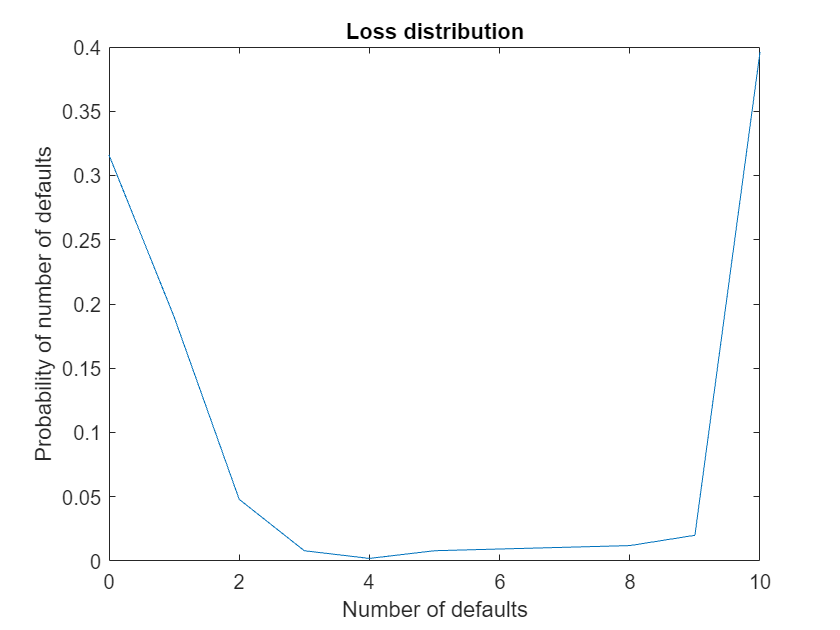

model_B3.plot_loss;

### Common noise

model_B3_cn = model_B3.common_noise(0.9);
model_B3_cn = model_B3_cn.sde_euler;
model_B3_cn.plot_trajectory;

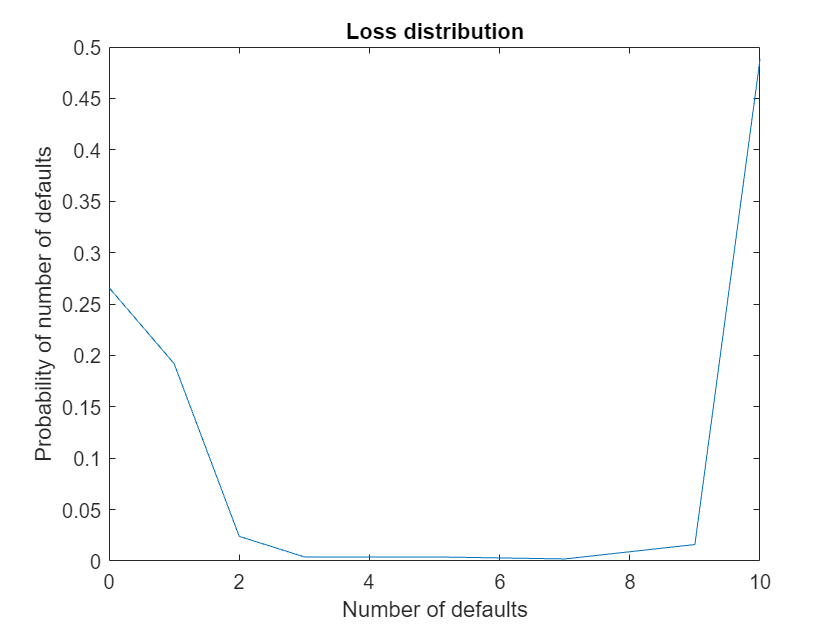

model_B3_cn.plot_loss;